%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)
clear all
close all 
clc


## Part 1: Understanding Saturation and Butterworth Filter

### 1.1

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1')

F = struct with fields:
      num: [0.5050 1.0100 0.5050]
    denom: [1 0.7478 0.2722]
      sys: [1×1 tf]


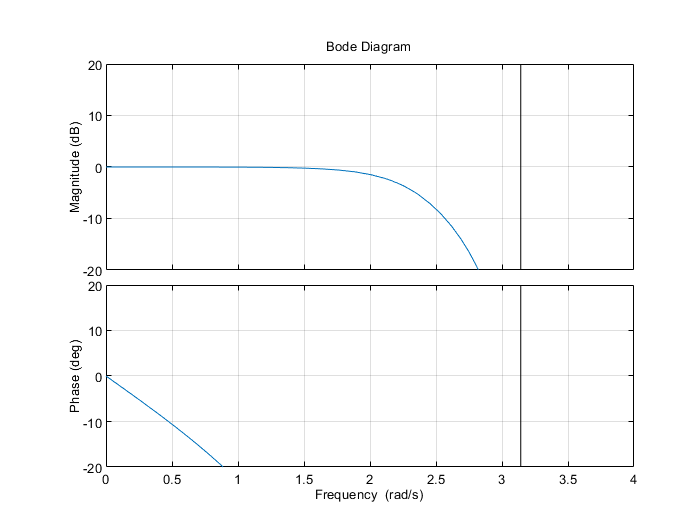


plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% w = 2.1954 rad/s is the -3 db point, f = w/2/pi = 0.3494


### 1.2

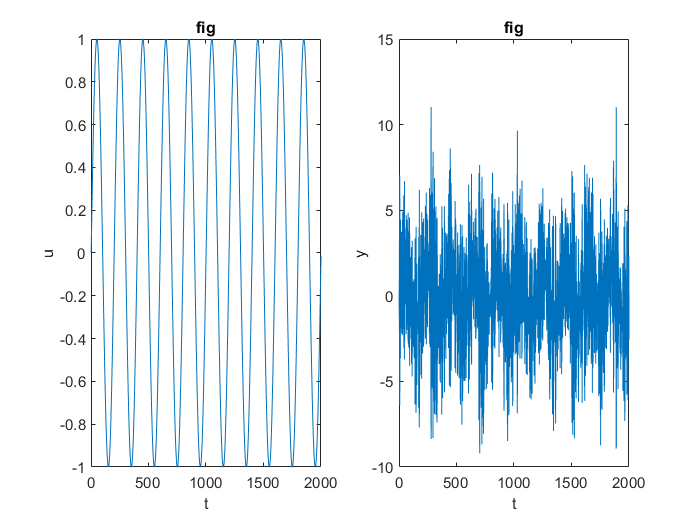

% nu = 100;
% previous_u = -100; 
% for mag=0:1:100
%     r = mag * ones(1,nu);
%     [u,y] = assignment_sys_36(r);
%     u(1)
%     previous_u
%     if (u(1) == previous_u)
%         fprintf("M is equal to %d", u(1));
%         break;
%     end
%     previous_u = u(1);
% end
% 
% % M is equal to 3

N = 2000;
f = 10;
offset = 0;
A = 1;

t = (0 : 1/N : 1)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1, 2, 1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1, 2, 2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");

% we now can know M is 3

## Part 2: Nonparametric identification

### 2.1. Nonparametric Identification

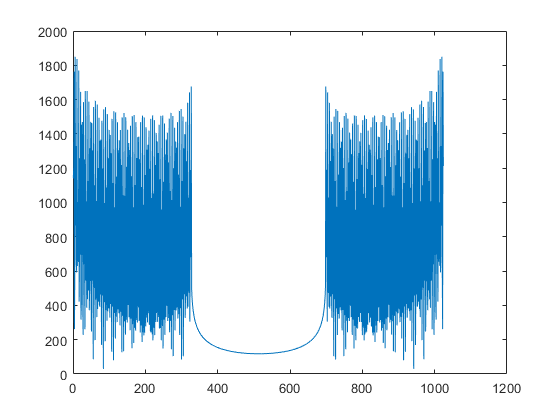

% system setup
N = 1024;
Ts = 1;
n_freq = 128;

% set the base frequency
f0 = 2/128;

% generate reference signal
f = [0: 1: N-1]/Ts;
r=0;
for i = 1: 1: n_freq
    r = r + 3 * sin(f0*i*f) + offset;
end

% analysis reference spectrum
w=fft(r);
plot(abs(w))

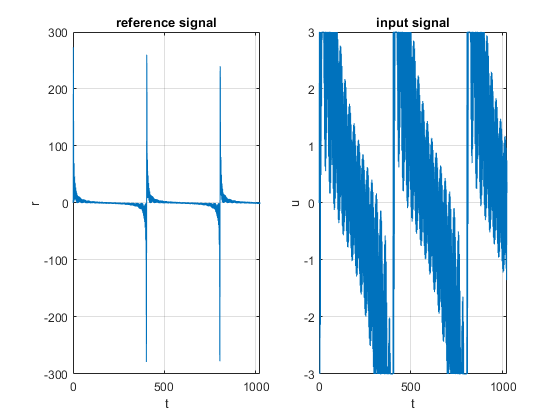


% plot reference signal
figure;
subplot(1, 2, 1)
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

% generate input-output
[u,y] = assignment_sys_36(r);
subplot(1, 2, 2)
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");


% ETFE identification
figure;
G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


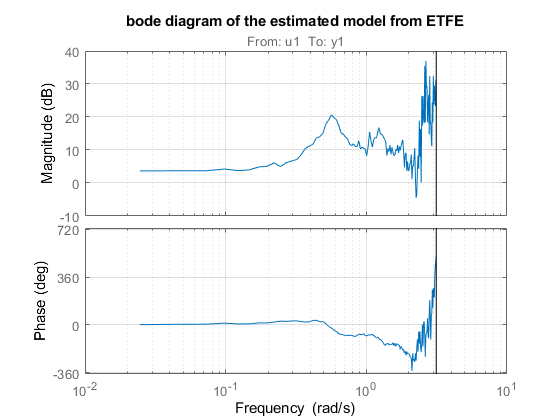

bode(G_ETFE)
grid on
title("bode diagram of the estimated model from ETFE");

### 2.3. Noise Spectrum Analysis

% Design a zero input, that is the output y will totally be noise signal
period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


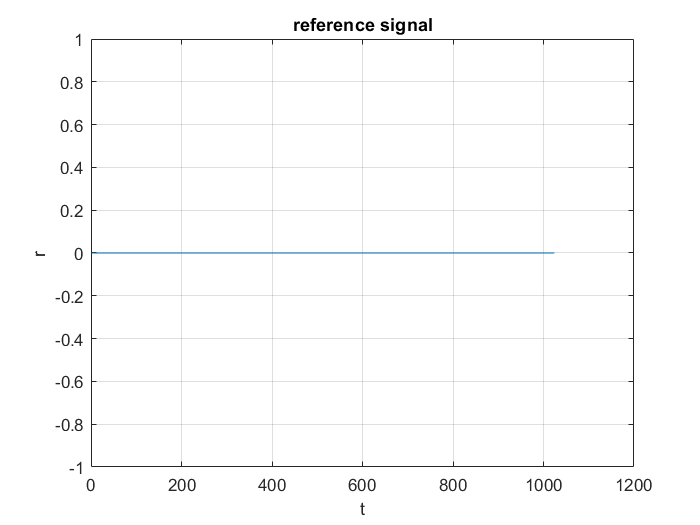



figure;
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

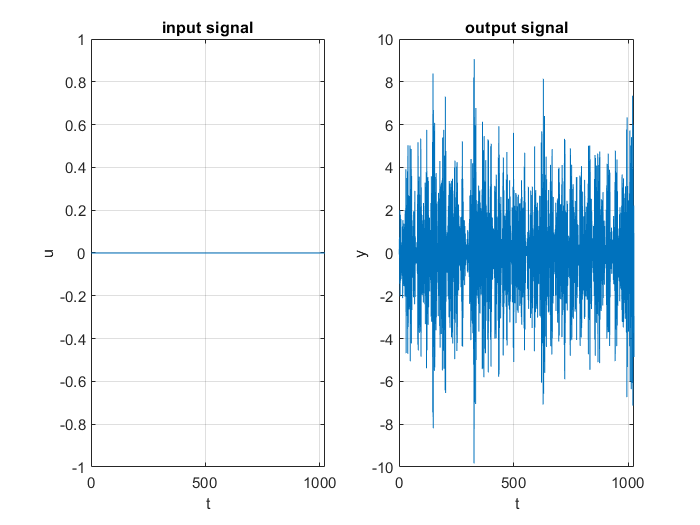


figure;
subplot(1, 2, 1)
[u,y] = assignment_sys_36(r);
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");

subplot(1, 2, 2)
plot(y)
grid on
xlabel("t"); ylabel("y"); title("output signal");

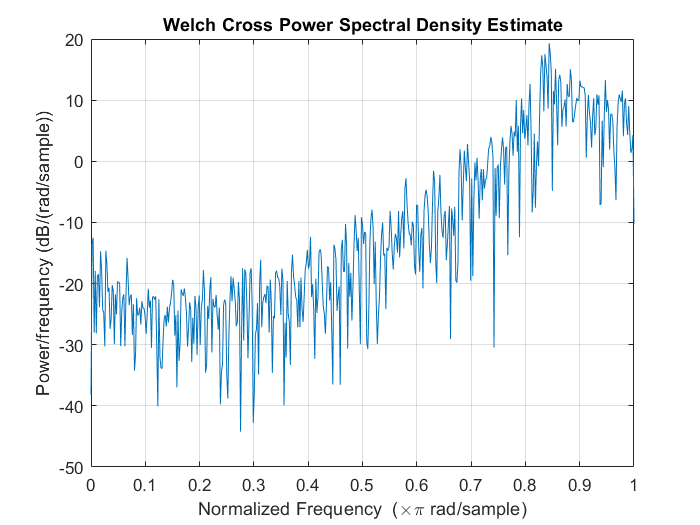


% analysis power specturm of noise signal
figure;
[Pv, W] = cpsd(y, y, 1024);
cpsd(y, y, 1024)

## Part 3: Expreiment Design

### 3.1

% prefer PRBS

### 3.2

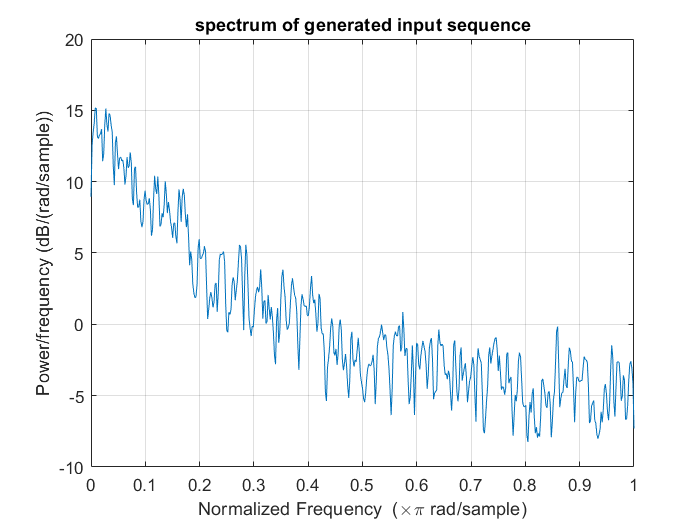

[r,P,w] = Generate_PRBS(0.9, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1 OE Model

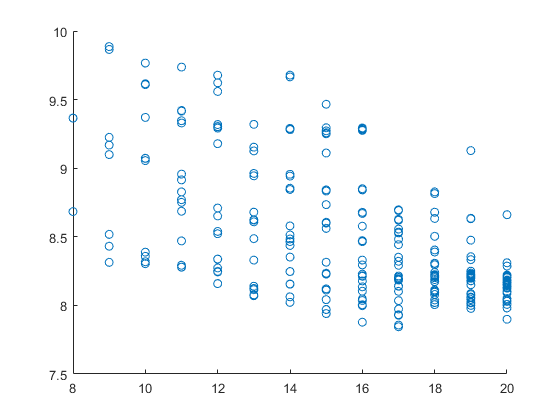

% Try OE Model

% divide the dataset into training set and validation set
[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
[u,y] = assignment_sys_36(r);
train_ratio = 0.7;
u_train = u([1: floor(train_ratio * length(u))]);
y_train = y([1: floor(train_ratio * length(y))]);
u_test = u([floor(train_ratio * length(u))+1: end]);
y_test = y([floor(train_ratio * length(y))+1: end]);

% prepare loop for order selection
order_upper = 20;
nb = 0; nf = 0; nk = 0;

OE.order.order_points = [];
OE.order.order_config = [];
OE.order.error = [];

for order_sum = 1: 1: order_upper
    
    for nb = 0: 1: order_sum
        
        for nf = 0: 1: order_sum - nb
            
            nk = order_sum - nb - nf;
            % for OE model, nk and nb cannot be zero at the same time
            if nk == 0 && nb == 0
                continue;
            end
            
            % identify a model
            temp_sys = oe(iddata(y_train, u_train), [nb, nf, nk]);
            % cost validate error
            temp_predict_error = pe(temp_sys, iddata(y_test, u_test), 1);
            temp_error = temp_predict_error.y' * temp_predict_error.y / length(y_test);
            
            % abort too abnormal result
            if temp_error > 10
                continue;
            end
            
            OE.order.order_points = [OE.order.order_points, order_sum];
            OE.order.order_config = [OE.order.order_config, [nb; nf; nk]];
            OE.order.error = [OE.order.error, temp_error];
            
        end
                  
    end
end
scatter(OE.order.order_points, OE.order.error);

% choose the optimal model
[M, I] = min(OE.order.error)

M = 7.8443

I = 149

OE.model_configuration = OE.order.order_config(:, I);
OE.model_order = OE.order.order_points(I);
OE.model_configuration

ans =      3
    13
     1


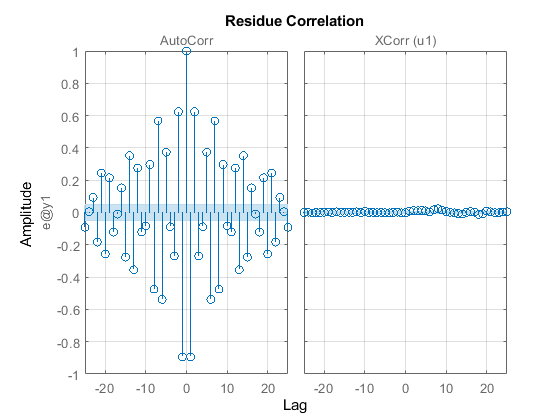

ans =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                                            
  B(z) = 1.845 z^-1 + 3.409 z^-2 + 2.146 z^-3                                                                                                    
                                                                                                                                                 
                                                                                                                                                 
  F(z) = 1 + 0.8406 z^-1 + 0.3022 z^-2 + 0.4231 z^-3 + 0.4438 z^-4 + 0.2359 z^-5 + 0.6503 z^-6 + 0.3221 z^-7 + 0.4022 z^-8 + 0.3943 z^-9         
                                                                                - 0.004987 z^-10 - 0.06114 z^-11 + 0.04156 z^-12 + 0.007416 z^-13
                                                                                                                      

% generate input-output signal
[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
[u,y] = assignment_sys_36(r);

% identify an OE model
OE.sys = oe(iddata(y, u), [3,13,1]);

% residual test
OE.resid = resid(iddata(y,u), OE.sys);
figure
resid(iddata(y,u), OE.sys)
grid on;

### 4.1 ARX Model

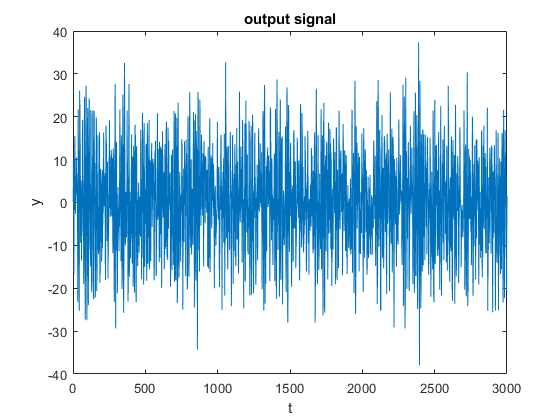

% figure;
% plot(y)
% xlabel("t"); ylabel("y"); title("output signal");


% identify an ARX model
G_ARX = arx([y u], [13 3 1])

G_ARX =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                   
                                                                                                                                                      
  A(z) = 1 + 1.296 z^-1 + 0.5344 z^-2 + 0.3912 z^-3 + 0.6189 z^-4 + 0.4278 z^-5 + 0.6143 z^-6 + 0.6082 z^-7 + 0.4791 z^-8 + 0.467 z^-9 + 0.1478 z^-10 
                                                                                                   - 0.1152 z^-11 - 0.006353 z^-12 + 0.0428 z^-13     
                                                                                                                                                      
  B(z) = 1.9 z^-1 + 4.075 z^-2 + 3.737 z^-3                                                                                                           
                                                                                      

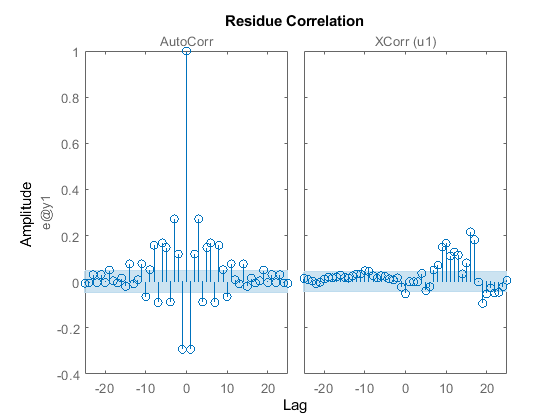

% good 10 9 1

% do the residual test
resid([y u], G_ARX)



% Using the systemIdentification Toolbox 
% Using the r to generate u and y, then import these two time domian data
% into the Toolbox
% Using the polynomial model estimation with ARX model
% In the Polynomial Model screen

## Part 5: Experimental verification of variance estimates

### 5.1. Variance Esitmate

% using the same r to generate the u and y, set the loop number as 100
Loop = 100;

[r,P,w] = Generate_PRBS(0.83, 1000, 3, false);

% using the parameter obtained from previous section
nb = 4; nf = 14; nk = 1;
result = zeros([Loop, nb+nk+nf-1], 'double');

for i = 1:Loop
    [u,y] = assignment_sys_36(r);
    G_OE = oe([y u], [nb nf nk]);
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result(i,:) = [B F];
end
clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result

result =     1.9087    2.4234    0.1523   -1.4409    0.3627   -0.3370    0.2812    0.2625   -0.1490    0.5813   -0.0238    0.0760    0.2772   -0.2768   -0.1667    0.2248   -0.1195    0.0188
    1.8831   -0.1079   -0.4496   -0.5560   -1.0013    0.6338   -0.0481   -0.5773    1.1625   -1.0978    0.8398   -0.2600   -0.2007    0.2579   -0.3959    0.3294   -0.1771    0.0458
    1.9297    4.3724    4.1378    0.7133    1.4359    0.6838    0.5005    0.7142    0.4493    0.7123    0.7192    0.5070    0.5618    0.2589   -0.1784    0.0354    0.0601   -0.0443
    1.7221    4.0345    2.5423    0.3127    1.0790    0.3299    0.5562    0.4359    0.3892    0.6327    0.4319    0.4918    0.3786    0.0966   -0.0658   -0.0341    0.0999   -0.0662
    1.5909    5.5699    6.2094    2.9568    1.9134    1.5006    0.7885    0.9118    0.8655    0.9386    1.0690    0.9479    0.7929    0.5366    0.0165   -0.0781    0.0730    0.0389
    1.7972    3.1315    1.7525   -0.5190    0.6691    0.2340    0.2656    0.4048    0.

### 5.2

% due to the existance of the noise, each realization is different from
% each other


### 5.3. Variance Comparison

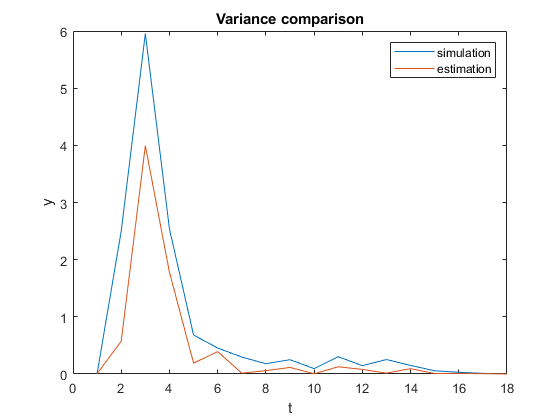

cov = getcov(G_OE);

cov_est = diag(cov)';

cov_sim = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim(1, k) = mean(result(:, k));
    cov_sim(2, k) = var(result(:, k));
end

% figure;
% plot(result(:,k))
% xlabel("t"); ylabel("y"); title("output signal");


figure;
plot(cov_sim(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance comparison");


clear k

### 5.4

result_54 = zeros([Loop, nb+nk+nf-1], 'double');

% for i = 1:Loop
%     [u,y] = assignment_sys_36(r);
%     G_OE = oe([y u], [nb nf nk]);
%     F_init = G_OE.Structure.F.Value;
%     B_init = G_OE.Structure.B.Value;
%     M_init = idpoly([], B_init, [], [], F_init);
%     M_oe = oe([y u], M_init);
%     F = G_OE.Structure.F.Value(2:1:end);
%     B = G_OE.Structure.B.Value(2:1:end);
%     result_54(i,:) = [B F];
% end

OEopt = oeOptions;
OEopt.SearchOptions.Tolerance = 0.0001;

for i = 1:Loop
    
    % Generate new data
    [u,y] = assignment_sys_36(r);
    
    if i ==1
        
        % generate an initial OE model
        M_oe = oe([y,u], [nb, nf, nk], OEopt);
        
    else
        % update starting point
        B_init = median(result_54([1: 1: i], [1: 1: nb]),1);
        F_init = median(result_54([1: 1: i], [nb+1: 1: end]),1);
        M_init = idpoly([], [1, B_init], [], [], [1, F_init]);
        
        % start OE model identification from the starting point
        M_oe = oe([y u], M_init, OEopt);
    end
    
    % record the parameter
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result_54(i,:) = [B F];
           
end
    

clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result_54

result_54 =     1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744    0.2729    0.6264    0.3169    0.3863    0.3847   -0.0359   -0.0457   -0.0082    0.0666   -0.0525
    1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744    0.2729    0.6264    0.3169    0.3863    0.3847   -0.0359   -0.0457   -0.0082    0.0666   -0.0525
    1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744    0.2729    0.6264    0.3169    0.3863    0.3847   -0.0359   -0.0457   -0.0082    0.0666   -0.0525
    1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744    0.2729    0.6264    0.3169    0.3863    0.3847   -0.0359   -0.0457   -0.0082    0.0666   -0.0525
    1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744    0.2729    0.6264    0.3169    0.3863    0.3847   -0.0359   -0.0457   -0.0082    0.0666   -0.0525
    1.7842    3.6344    1.9998   -0.1133    0.9215    0.1563    0.5139    0.3744   

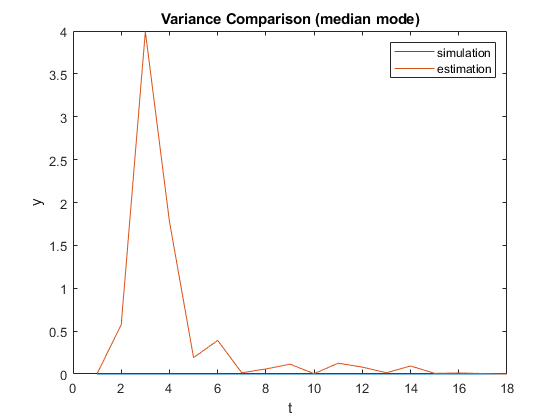

cov_sim_54 = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim_54(1, k) = mean(result_54(:, k));
    cov_sim_54(2, k) = var(result_54(:, k));
end

% figure;
% plot(result_54(:,k))
% xlabel("t"); ylabel("y"); title("output signal");
% 

figure;
plot(cov_sim_54(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance Comparison (median mode)");


clear k Loop

## Part 6: Estimation of a Box Jenkins model for minimum variance

### 6.1. Identify an BJ model

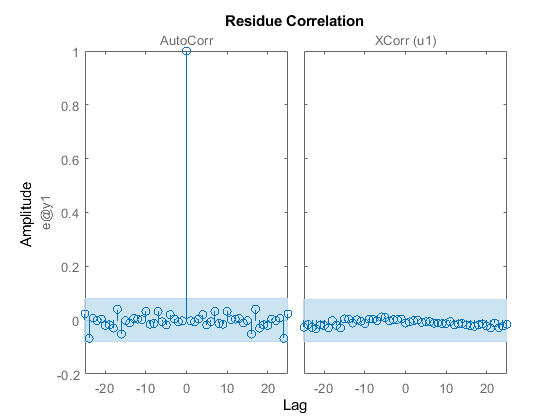

nb = 3;
nf = 13;
nc = 3;
nd = 5;
nk = 1;

% identify an BJ model
BJ.sys = bj(iddata(y,u), [nb, nc, nd, nf, nk]);

% resid test
resid(iddata(y,u), BJ.sys)

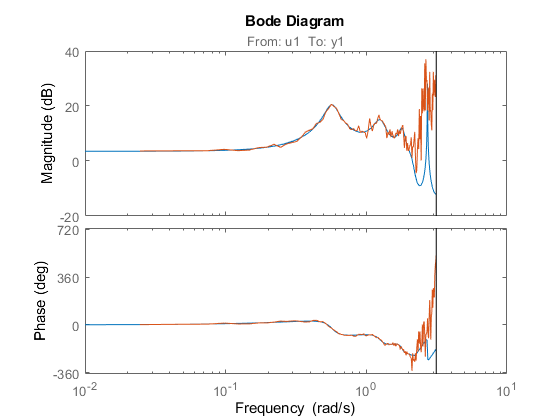


% bode graph of ETFE and identifed BJ model
bode(BJ.sys, G_ETFE)


% TODO: bode graph of noise signal power spectrum and identified H in the
% BJ model
% bode(BJ.sys.H)

Error using InputOutputModel/subsref (line 43)
No property of the class "idpoly" matches the identifier "H". Use PROPERTIES to get the list of properties for this class.

### 6.2. compute the variance

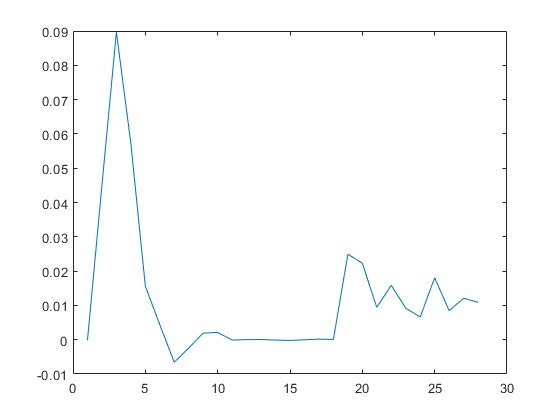

cov = getcov(BJ.sys);
figure 
plot(cov(2,:))

## Function Used

function [r,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% u(t) = u(t-1) with probability p
%% u(t) = -u(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    u : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        r(1) = mag;
    else
        r(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            r(i) = r(i-1);
        else
            r(i) = -r(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(r,r,N);
    
    if (plt_flag == true)
        cpsd(r, r);
        title('spectrum of generated input sequence')
    end
    
end